# HW 4 Problem 5

We observe that our system has 4 variables, $a_0, a_2, a_4,b_2$, so for $n>4$ we have an overdetermined system.  Thus, we are doing a least squares style approximation to solve the following systems of equations


$$f(x_i)\approx\frac{a_0+a_2x_i^2+a_4x_i^4}{1+b_2x_i^2}, \forall i\in\{0, ... ,n\}$$


Which is equivalent to solving,


$$(1+b_2x_i^2)f(x_i)\approx a_0+a_2x_i^2+a_4x_i^4, \forall i\in \{0,..., n\}$$


After one more transformation we get the following linear system, as $x_i ,f\left(x_i \right)$are both known:


$$f(x_i)\approx a_0+a_2x_i^2+a_4x_i^4-b_2f(x_i)x_i^2, \forall i\in\{0,...,n\}$$


Thus we use our linear least squares to solve for $a_0 ,a_2 ,a_4 ,b_2$

n1=5;
n2=10;

We then use linspace to create n+3 equally spaced points between $-\frac{\pi }{2},\frac{\pi }{2}$ and then drop the end ponts in a new vector to create our node set.

nodes5=IntNodeLinSpacer(n1, -pi/2, pi/2);
nodes10=IntNodeLinSpacer(n2, -pi/2, pi/2);

Now we pass these to our LeastPade fuction to create our A matrix for linear least squares, and generate our b vector using $b_i =f\left(x_i \right)=\sin \left(x_i \right)$

A5=LeastPade(nodes5);
A10=LeastPade(nodes10);
b5=zeros(n1+1,1);
b10=zeros(n2+1,1);
for i=1:size(b5,1)
    b5(i,1)=cos(nodes5(i,1));
end
for i=1:size(b10,1)
    b10(i,1)=cos(nodes10(i,1));
end    

Finally, we simply solve our normal equation $A^T \textrm{Ax}=A^T b$

x5=(A5'*A5)\(A5'*b5)

x5 =     0.9991
   -1.2676
    0.3784
   -0.7889


x10=(A10'*A10)\(A10'*b10)

x10 =     1.0000
   -0.4649
    0.0242
    0.0351


We now compare these approximations against the initial cosine function

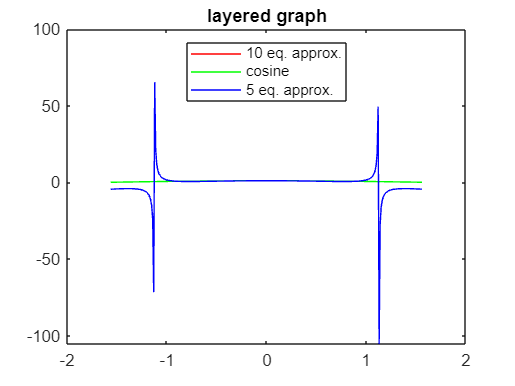

xinit=(-pi/2):.01:(pi/2);
x=zeros(1,size(xinit,2)-2);
for i=1:size(x,2)
    x(1,i)=xinit(1,i+1);
end
f=cos(x);
Pade5=zeros(1,size(x,2));
Pade10=zeros(1,size(x,2));
for i=1:size(x,2)
    Pade5(1,i)=(x5(1,1)+x5(2,1)*x(1,i)^2+x5(3,1)*x(1,i)^4/(1+x5(4,1)*x(1,i)^2));
    Pade10(1,i)=(x10(1,1)+x10(2,1)*x(1,i)^2+x10(3,1)*x(1,i)^4)/(1+x10(4,1)*x(1,i)^2);
end
plot(x, Pade10, 'red');
hold on
plot(x, f, 'green');
plot(x,Pade5, 'blue');
legend({'10 eq. approx.', 'cosine', '5 eq. approx.'}, 'Location', 'north');
title('layered graph');
hold off;

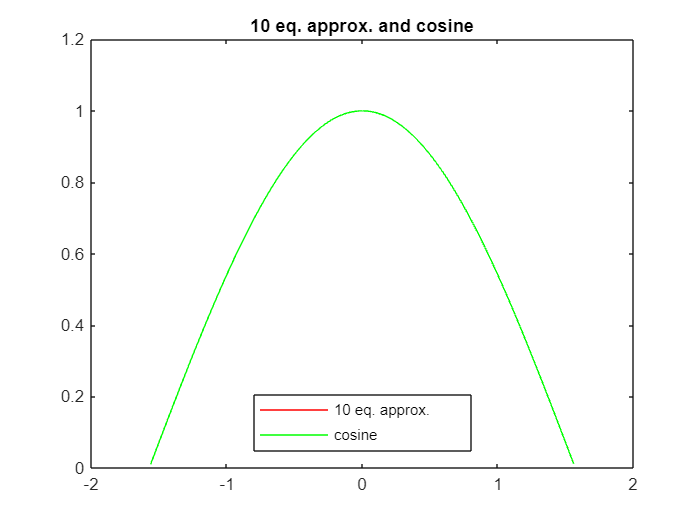

plot(x, Pade10, 'red');
hold on
plot(x, f, 'green');
legend({'10 eq. approx.', 'cosine'}, 'Location', 'south' );
title('10 eq. approx. and cosine')
hold off

As can be seen there appear to be some asymptotes in the n=5 case, but the n=10 case is remarkably close to the actual cosine function.  I'm guessing the issue came from the warning about our matrix being approximately singlular.  However, looking at the date the n=5 approximation does a better, but no much better, job once further away from the end points.  See graph after this section.  Maybe this is relating to the issues with interpolating using equally spaced points as our polynomial got squeezed at the end points.

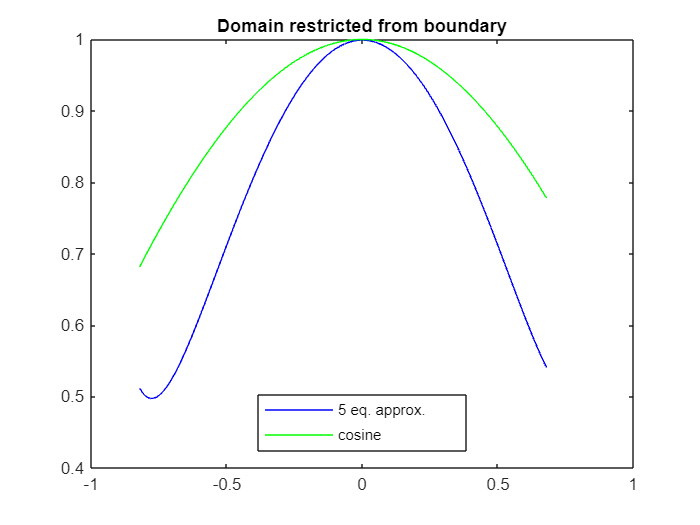

plot(x(1,75:225), Pade5(1,75:225), 'blue');
hold on
plot(x(1, 75:225), f(1, 75:225), 'green');
legend({'5 eq. approx.', 'cosine'}, 'Location', 'south');
title('Domain restricted from boundary')
hold off

Essentially we are seeing that as we use more points for our evaluation, the difference is being minimized.  Which makes sense, since as $n\to \infty \;$we would move to minimizing the infinite squared sum which is roughly minimizing their difference under the $L^2$ norm.